Gradients with respect to x and y

syms x y;
f1 = @(x,y) 2.*x + 3.*y + 1;
f2 = @(x,y) (x).^2 + (y).^2 - x.*y - 5;
f3 = @(x, y) (x-5).*cos(y-5) - (y-5).*sin(x-5);

g1 = gradient(f1,[x,y])

$$g1 = \left(\begin{array}{c} 2\\ 3 \end{array}\right)$$

g2 = gradient(f2,[x,y])

$$g2 = \left(\begin{array}{c} 2\,x-y\\ 2\,y-x \end{array}\right)$$

g3 = gradient(f3,[x,y])

$$g3 = \left(\begin{array}{c} \cos\left(y-5\right)-\cos\left(x-5\right)\,\left(y-5\right)\\ -\sin\left(x-5\right)-\sin\left(y-5\right)\,\left(x-5\right) \end{array}\right)$$

## 2D Contour Plots

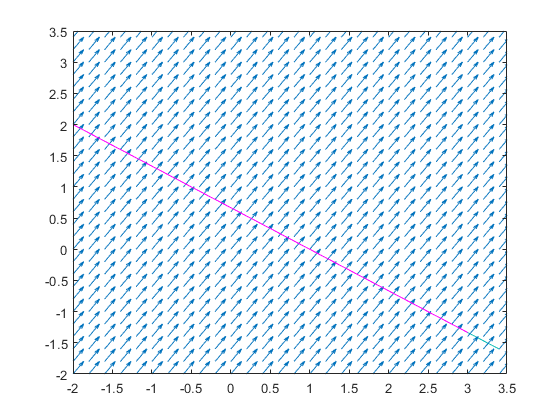

% 2D contour plots in range -2 to 3.5

%% First Function f1
[X, Y] = meshgrid(-2:0.2:3.5);
% tangent line
x1 = -2 : 3.5;
m1 = -2/3;
b1 = 2/3;
y1 = m1*x1 + b1;
% level set and gradients
F1 = 2.*X + 3.*Y + 1;
v = [3, 3];
contour(X, Y, F1, v)
[U, V] = gradient(F1, 0.2, 0.2);
hold on
quiver(X, Y, U, V);
plot(x1, y1, 'm')
xlim([-2 3.5])
ylim([-2 3.5])
hold off

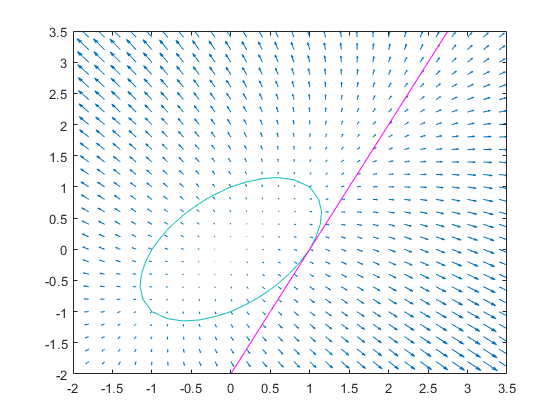


%% Second function f2
[X, Y] = meshgrid(-2:0.2:3.5);
% tangent line through (1, 0)
x2 = -2 : 3.5;
m2 = 2;
b2 = -2;
y2 = m2*x2 + b2;
% level set and gradients
F2 = X.^2 + Y.^2 - X.*Y - 5;
v = [-4, -4];
contour(X, Y, F2, v)
[U, V] = gradient(F2, 0.2, 0.2);
hold on
quiver(X, Y, U, V);
plot(x2, y2, 'm')
xlim([-2 3.5]);
ylim([-2 3.5]);
hold off

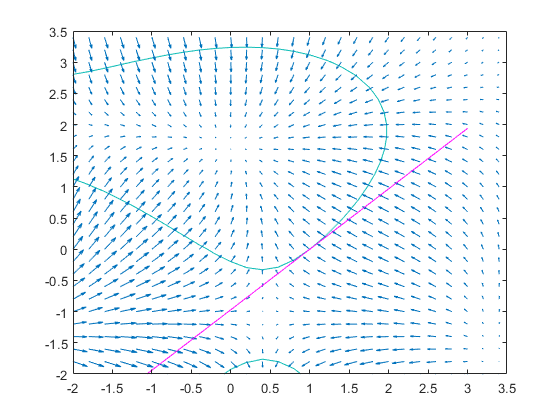


%% Third function f3
[X, Y] = meshgrid(-2:0.2:3.5);
% tangent line through (1, 0)
x3 = -2 : 3.5;
m3 = -(cos(5)+5*cos(4))/(sin(4)-4*sin(5));
b3 = (cos(5) + 5*cos(4))/(sin(4)-4*sin(5));
y3 = m3*x3 + b3;
% level set and gradients
F3 = (X-5).*cos(Y-5) - (Y-5).*sin(X-5);
v = [2.6494, 2.6494];
contour(X, Y, F3, v)
[U, V] = gradient(F3, 0.2, 0.2);
% plot
hold on
quiver(X, Y, U, V);
plot(x3, y3, 'm')
xlim([-2 3.5]);
ylim([-2 3.5]);
hold off 

## 3D Contour Plots

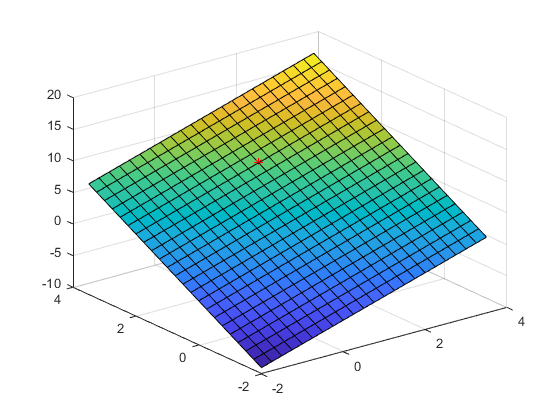

% point (1, 0)
x0 = 1;
y0 = 0;

%% first function
[xx,yy] = meshgrid(-2:0.25:3.5);
[f1x,f1y] = gradient(f1(xx,yy),0.25);
t = (xx == x0) & (yy == y0); %tangent at that point
indt = find(t);
f1x0 = f1x(indt);
f1y0 = f1y(indt);
z = @(x,y) f1(x0,y0) + f1x0*(x-x0) + f1y0*(y-y0); % tangent eqn
% plot surface
surf(xx,yy,f1(xx,yy))
hold on
% plot tangent
surf(xx,yy,z(xx,yy))
plot3(1,2,f1(1,2),'r*')
hold off

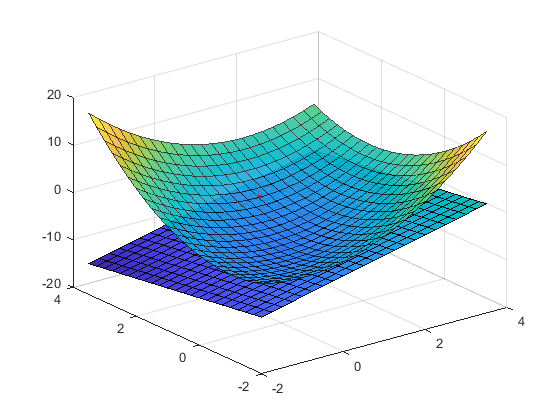


%% second function
[xx,yy] = meshgrid(-2:0.25:3.5);
[f2x,f2y] = gradient(f2(xx,yy),0.25);
t = (xx == x0) & (yy == y0); %tangent at that point
indt = find(t);
f2x0 = f2x(indt);
f2y0 = f2y(indt);
z = @(x,y) f2(x0,y0) + f2x0*(x-x0) + f2y0*(y-y0); % tangent eqn
% plot surface
surf(xx,yy,f2(xx,yy),'EdgeAlpha',0.7,'FaceAlpha',0.9)
hold on
% plot tangent
surf(xx,yy,z(xx,yy))
plot3(1,2,f2(1,2),'r*')
hold off

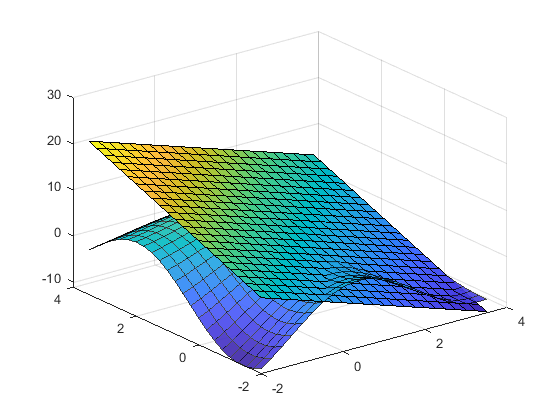


%% third function
[xx,yy] = meshgrid(-2:0.25:3.5);
[f3x,f3y] = gradient(f3(xx,yy),0.25);
t = (xx == x0) & (yy == y0); %tangent at that point
indt = find(t);
f3x0 = f3x(indt);
f3y0 = f3y(indt);
z = @(x,y) f3(x0,y0) + f3x0*(x-x0) + f3y0*(y-y0); % tangent eqn
% plot surface
surf(xx,yy,f3(xx,yy),'EdgeAlpha',0.7,'FaceAlpha',0.9)
hold on
% plot tangent
surf(xx,yy,z(xx,yy))
plot3(1,2,f3(1,2),'r*')
hold off